# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 21-Feb-2020 16:15:23

## Create the Layer Graph

Create the layer graph variable to contain the network's layers.

lgraph = layerGraph();

## Add the Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([2 1024 1],"Name","input")
    convolution2dLayer([3 7],64,"Name","conv1","Padding",[1 1 3 3],"Stride",[1 2])
    reluLayer("Name","relu1")
    maxPooling2dLayer([1 3],"Name","pool1","Padding",[0 0 1 1],"Stride",[1 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 1],32,"Name","pre_conv_a","Padding",[1 1 0 0])
    reluLayer("Name","pre_relu_a")
    averagePooling2dLayer([1 3],"Name","pre_pool_a","Padding",[0 0 1 1],"Stride",[1 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 3],32,"Name","pre_conv_b","Padding",[0 0 1 1],"Stride",[1 2])
    reluLayer("Name","pre_relu_b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(2,"Name","pre_concat");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","jump_conv1x1","Stride",[1 2])
    reluLayer("Name","jump_relu1x1")
    maxPooling2dLayer([1 3],"Name","jump_poolingA","Padding",[0 0 1 1],"Stride",[1 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([1 3],"Name","post_pooling","Padding",[0 0 1 1],"Stride",[1 2])
    convolution2dLayer([1 1],32,"Name","mblockA_conv_a")
    reluLayer("Name","mblockA_relu_a")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 3],48,"Name","mblockA_conv_c","Padding",[0 0 1 1],"Stride",[1 2])
    reluLayer("Name","mblockA_relu_c")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockA_conv_d","Stride",[1 2])
    reluLayer("Name","mblockA_relu_d")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 1],48,"Name","mblockA_conv_b","Padding",[1 1 0 0])
    reluLayer("Name","mblockA_relu_b")
    averagePooling2dLayer([1 3],"Name","mblockA_pool_b","Padding",[0 0 1 1],"Stride",[1 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","mixA");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_mixA");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockB_conv_a")
    reluLayer("Name","mblockB_relu_a")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 1],48,"Name","mblockB_conv_b","Padding",[1 1 0 0])
    reluLayer("Name","mblockB_relu_b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockB_conv_d")
    reluLayer("Name","mblockB_relu_d")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 3],48,"Name","mblockB_conv_c","Padding",[0 0 1 1])
    reluLayer("Name","mblockB_relu_c")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","mixB");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_mixB");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = maxPooling2dLayer([2 2],"Name","jump_poolingC","Padding",[1 0 0 0],"Stride",[1 2]);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockC_conv_a")
    reluLayer("Name","mblockC_relu_a")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 3],48,"Name","mblockC_conv_c","Padding",[0 0 1 1],"Stride",[1 2])
    reluLayer("Name","mblockC_relu_c")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockC_conv_d","Stride",[1 2])
    reluLayer("Name","mblockC_relu_d")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 1],48,"Name","mblockC_conv_b","Padding",[1 1 0 0])
    reluLayer("Name","mblockC_relu_b")
    averagePooling2dLayer([1 3],"Name","mblockC_pool_b","Padding",[0 0 1 1],"Stride",[1 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","mixC");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_mixC");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockD_conv_a")
    reluLayer("Name","mblockD_relu_a")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 1],48,"Name","mblockD_conv_b","Padding",[1 1 0 0])
    reluLayer("Name","mblockD_relu_b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockD_conv_d")
    reluLayer("Name","mblockD_relu_d")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 3],48,"Name","mblockD_conv_c","Padding",[0 0 1 1])
    reluLayer("Name","mblockD_relu_c")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","mixD");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_mixD");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = maxPooling2dLayer([2 2],"Name","jump_poolingE","Padding",[1 0 0 0],"Stride",[1 2]);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockE_conv_a")
    reluLayer("Name","mblockE_relu_a")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockE_conv_d","Stride",[1 2])
    reluLayer("Name","mblockE_relu_d")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 1],48,"Name","mblockE_conv_b","Padding",[1 1 0 0])
    reluLayer("Name","mblockE_relu_b")
    maxPooling2dLayer([1 3],"Name","mblockE_pool_b","Padding",[0 0 1 1],"Stride",[1 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 3],48,"Name","mblockE_conv_c","Padding",[0 0 1 1],"Stride",[1 2])
    reluLayer("Name","mblockE_relu_c")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","mixE");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_mixE");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","mblockF_conv_a")
    reluLayer("Name","mblockF_relu_a")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","mblockF_conv_d")
    reluLayer("Name","mblockF_relu_d")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 3],96,"Name","mblockF_conv_c","Padding",[0 0 1 1])
    reluLayer("Name","mblockF_relu_c")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 1],96,"Name","mblockF_conv_b","Padding",[1 1 0 0])
    reluLayer("Name","mblockF_relu_b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","mixF");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","concat_all")
    averagePooling2dLayer([2 8],"Name","global_pool")
    fullyConnectedLayer(24,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classifier")];
lgraph = addLayers(lgraph,tempLayers);

## Connect the Layer Branches

Connect all the branches of the network to create the network's graph.

lgraph = connectLayers(lgraph,"pool1","pre_conv_a");
lgraph = connectLayers(lgraph,"pool1","pre_conv_b");
lgraph = connectLayers(lgraph,"pre_relu_b","pre_concat/in1");
lgraph = connectLayers(lgraph,"pre_pool_a","pre_concat/in2");
lgraph = connectLayers(lgraph,"pre_concat","jump_conv1x1");
lgraph = connectLayers(lgraph,"pre_concat","post_pooling");
lgraph = connectLayers(lgraph,"jump_poolingA","add_mixA/in2");
lgraph = connectLayers(lgraph,"mblockA_relu_a","mblockA_conv_c");
lgraph = connectLayers(lgraph,"mblockA_relu_a","mblockA_conv_d");
lgraph = connectLayers(lgraph,"mblockA_relu_a","mblockA_conv_b");
lgraph = connectLayers(lgraph,"mblockA_relu_c","mixA/in1");
lgraph = connectLayers(lgraph,"mblockA_relu_d","mixA/in3");
lgraph = connectLayers(lgraph,"mblockA_pool_b","mixA/in2");
lgraph = connectLayers(lgraph,"mixA","add_mixA/in1");
lgraph = connectLayers(lgraph,"add_mixA","mblockB_conv_a");
lgraph = connectLayers(lgraph,"add_mixA","add_mixB/in2");
lgraph = connectLayers(lgraph,"mblockB_relu_a","mblockB_conv_b");
lgraph = connectLayers(lgraph,"mblockB_relu_a","mblockB_conv_d");
lgraph = connectLayers(lgraph,"mblockB_relu_a","mblockB_conv_c");
lgraph = connectLayers(lgraph,"mblockB_relu_b","mixB/in1");
lgraph = connectLayers(lgraph,"mblockB_relu_d","mixB/in3");
lgraph = connectLayers(lgraph,"mblockB_relu_c","mixB/in2");
lgraph = connectLayers(lgraph,"mixB","add_mixB/in1");
lgraph = connectLayers(lgraph,"add_mixB","jump_poolingC");
lgraph = connectLayers(lgraph,"add_mixB","mblockC_conv_a");
lgraph = connectLayers(lgraph,"jump_poolingC","add_mixC/in2");
lgraph = connectLayers(lgraph,"mblockC_relu_a","mblockC_conv_c");
lgraph = connectLayers(lgraph,"mblockC_relu_a","mblockC_conv_d");
lgraph = connectLayers(lgraph,"mblockC_relu_a","mblockC_conv_b");
lgraph = connectLayers(lgraph,"mblockC_relu_d","mixC/in3");
lgraph = connectLayers(lgraph,"mblockC_relu_c","mixC/in2");
lgraph = connectLayers(lgraph,"mblockC_pool_b","mixC/in1");
lgraph = connectLayers(lgraph,"mixC","add_mixC/in1");
lgraph = connectLayers(lgraph,"add_mixC","mblockD_conv_a");
lgraph = connectLayers(lgraph,"add_mixC","add_mixD/in2");
lgraph = connectLayers(lgraph,"mblockD_relu_a","mblockD_conv_b");
lgraph = connectLayers(lgraph,"mblockD_relu_a","mblockD_conv_d");
lgraph = connectLayers(lgraph,"mblockD_relu_a","mblockD_conv_c");
lgraph = connectLayers(lgraph,"mblockD_relu_b","mixD/in2");
lgraph = connectLayers(lgraph,"mblockD_relu_d","mixD/in3");
lgraph = connectLayers(lgraph,"mblockD_relu_c","mixD/in1");
lgraph = connectLayers(lgraph,"mixD","add_mixD/in1");
lgraph = connectLayers(lgraph,"add_mixD","jump_poolingE");
lgraph = connectLayers(lgraph,"add_mixD","mblockE_conv_a");
lgraph = connectLayers(lgraph,"jump_poolingE","add_mixE/in2");
lgraph = connectLayers(lgraph,"mblockE_relu_a","mblockE_conv_d");
lgraph = connectLayers(lgraph,"mblockE_relu_a","mblockE_conv_b");
lgraph = connectLayers(lgraph,"mblockE_relu_a","mblockE_conv_c");
lgraph = connectLayers(lgraph,"mblockE_relu_d","mixE/in3");
lgraph = connectLayers(lgraph,"mblockE_pool_b","mixE/in2");
lgraph = connectLayers(lgraph,"mblockE_relu_c","mixE/in1");
lgraph = connectLayers(lgraph,"mixE","add_mixE/in1");
lgraph = connectLayers(lgraph,"add_mixE","mblockF_conv_a");
lgraph = connectLayers(lgraph,"add_mixE","concat_all/in2");
lgraph = connectLayers(lgraph,"mblockF_relu_a","mblockF_conv_d");
lgraph = connectLayers(lgraph,"mblockF_relu_a","mblockF_conv_c");
lgraph = connectLayers(lgraph,"mblockF_relu_a","mblockF_conv_b");
lgraph = connectLayers(lgraph,"mblockF_relu_d","mixF/in3");
lgraph = connectLayers(lgraph,"mblockF_relu_c","mixF/in1");
lgraph = connectLayers(lgraph,"mblockF_relu_b","mixF/in2");
lgraph = connectLayers(lgraph,"mixF","concat_all/in1");

## Clean Up Helper Variable

clear tempLayers;

## Plot the Layers

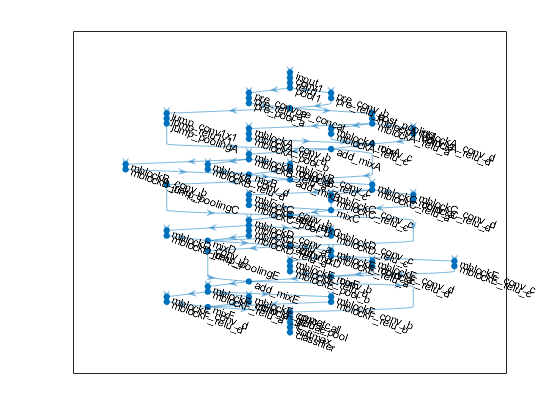

plot(lgraph);